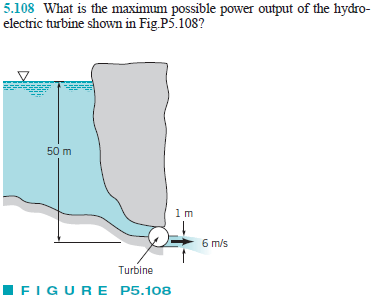

# inflow properties

u = symunit;
u1 = 0;
p1 = 0;
V1 = 0;
z1 = 50*u.m;

# outflow properties

u2 = 0;
p2 = 0;
V2 = 6*u.m/u.s;
z2 = 0;

# mass flow rate

rho = 999*u.kg/u.m^3;
D2 = 1*u.m;
A2 = sympi*D2^2/4;
mdot = rho*A2*V2;

# conservation of energy

g = 9.81*u.m/u.s^2;
Wdotshaft = mdot*(u2-u1+(p2-p1)/rho+(V2^2-V1^2)/2+g*(z2-z1));
Wdotshaft = rewrite(Wdotshaft, u.MW);
Wdotshaft_vpa = vpa(Wdotshaft, 3) %#ok

$$Wdotshaft\_vpa = -2.22\,\mathrm{MW}$$

clear Wdotshaft_vpa;